# Block MATLAB Execution While Modal Dialog Box Displays

Prevent program execution from continuing until the user responds to a modal dialog box.

Create UI axes in a UI figure.

fig = uifigure;
fig.Position = [500 500 500 350]; 
ax = uiaxes(fig);

Create a modal alert dialog box that displays a message. Specify a `CloseFcn` callback that calls the `uiresume` function when the user responds to the dialog box.

uialert(fig,'A line plot will be created in the axes.', ...
    'Program Information','Icon','info','CloseFcn','uiresume(fig)')

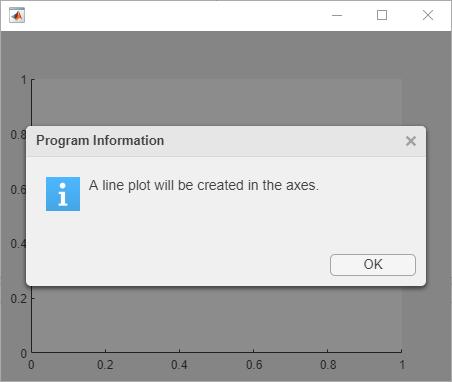

Wait for the user to respond to the alert dialog box, and then display a line plot in the axes when program execution resumes.

uiwait(fig)
plot(ax,1:10)

To resume program execution and plot the line, click **OK** or close the dialog box.

*Copyright 2019 The MathWorks, Inc.*